# Classification LSTM Neural Network for CI Impedance Sensing

## Load Data

retrain = false;
load('D:\Trevor\My Documents\MED lab\Cochlear R01\Impedance Sensing\Experiments\Dissertation data\Zsense_dissertation-data_2-23.mat');
load('D:\Trevor\My Documents\MED lab\Cochlear R01\Impedance Sensing\Experiments\Dissertation data\Zsense_LSTMclassify-min.mat');
net = netZsensing;
net.resetState;

## Prepare Training/Validation Data

Sort areas into bins

bin_edges = [0 .5 1 4]; % [mm^2] area bins 
bin_names = {'Modiolar','Middle','Lateral'};
numClasses = length(bin_names);

% use impedance and moving average as features
% XTrain = cell(8,1);
% YTrain = cell(8,1);
% XValidation = cell(4,1);
% for ii=1:4
%     XTrain{2*ii-1}  = [trial4.Z{ii}; trial4.Z_ema{ii}];
%     XTrain{2*ii}    = [trial7.Z{ii}; trial7.Z_ema{ii}];
%     XValidation{ii} = [trial6.Z{ii}; trial6.Z_ema{ii}];
%     
%     YTrain{2*ii-1} = trial4.A{ii};
%     YTrain{2*ii}   = trial7.A{ii};
% end

% XTrain = [trial4.Z_bias; trial7.Z_bias];
XTrain = [cellfun(@minus,trial4.Z,trial4.Z_min,'Un',0); ...
          cellfun(@minus,trial7.Z,trial7.Z_min,'Un',0)];
% XTrain = [trial4.Z; trial7.Z];
YTrain = [trial4.A; trial7.A];
for ii = 1:length(YTrain)
    YTrain{ii} = discretize(YTrain{ii}, bin_edges);           % convert to bin number
    YTrain{ii} = categorical(YTrain{ii}, 1:length(bin_names), bin_names); % convert to bin name
end

XValidation = cellfun(@minus,trial6.Z,trial6.Z_min,'Un',0);
% XValidation = trial6.Z_bias;
% XValidation = trial6.Z;
YValidation = trial6.A;
for ii = 1:length(YValidation)
    YValidation{ii} = discretize(YValidation{ii}, bin_edges);
    YValidation{ii} = categorical(YValidation{ii}, 1:length(bin_names), bin_names);
end

## Create Network Layers

numFeatures = size(XTrain{1},1); % Z (& EMA)
numHiddenUnits = 120;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

## Train Network

Options

if retrain == true
    max_epochs = 150;
    mini_batch_size = 1;
    gradient_threshold = .1;
    learn_rate = 2.0e-3;
    %     'ValidationData',{XValidation,YValidation}, ...
    
    options = trainingOptions('adam', ...
        'SquaredGradientDecayFactor',.9999, ...
        'MaxEpochs',max_epochs, ...
        'MiniBatchSize',mini_batch_size, ...
        'InitialLearnRate',learn_rate, ...
        'LearnRateSchedule',"piecewise", ...
        'ValidationFrequency', 25, ...
        'ValidationPatience', 3, ...
        'GradientThreshold',gradient_threshold, ...
        'Verbose',false, ...
        'Plots','training-progress');

Train

    net = trainNetwork(XTrain, YTrain, layers, options);
end

## Compute Prediction with Validation Data

Compute prediction

YPred = classify(net, XValidation);

## Analysis

Plot: overall prediction accuracy (confusion matrix)

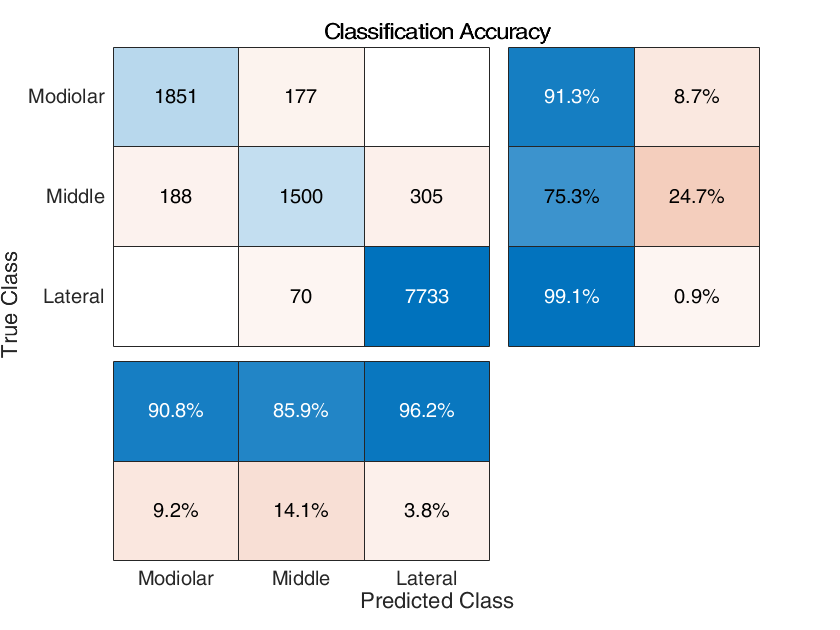

YPred_all = [];
YValidation_all = [];
for ii=1:length(YPred)
    YValidation_all = [YValidation_all, YValidation{ii}];
    YPred_all = [YPred_all, YPred{ii}];
end
figure
% cm = confusionchart(YValidation_all,YPred_all,'Normalization','column-normalized','RowSummary','row-normalized');
% cm = confusionchart(YValidation_all,YPred_all,'Normalization','column-normalized');
cm = confusionchart(YValidation_all,YPred_all,'RowSummary','row-normalized','ColumnSummary','column-normalized');
cm.Title = 'Classification Accuracy';

Plot: prediction vs time

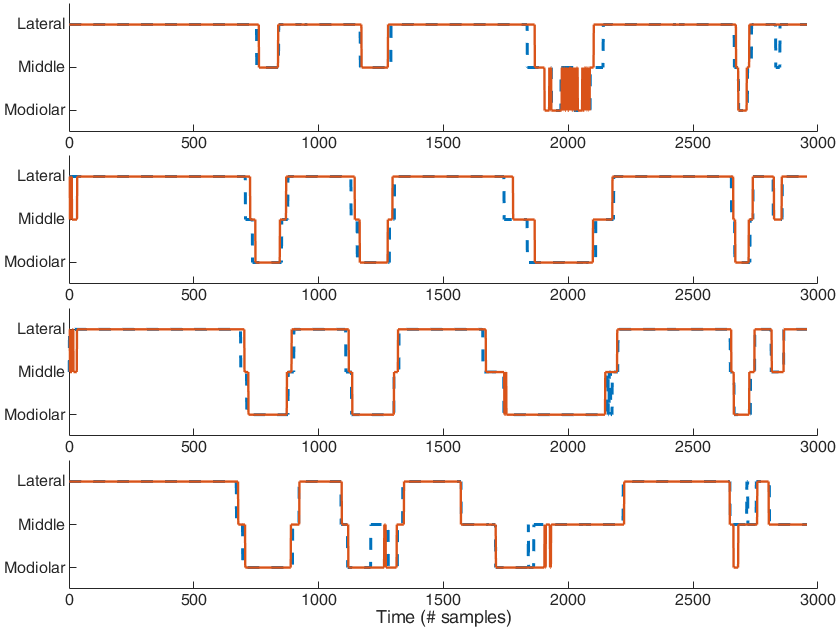

class_colors = [1 0.1 0.1; 1 .6 .1; 0 .1 1];

figure
for ii=1:length(YValidation)
    ax_pred(ii) = subplotXmanyY_er(4,1,ii);
    hold on
    plot(YValidation{ii}, '--', 'LineWidth',1.5)
    plot(YPred{ii},'LineWidth',1.2)
end
linkaxes(ax_pred,'x')
xlabel('Time (# samples)')
hold off

Plot: true area vs time

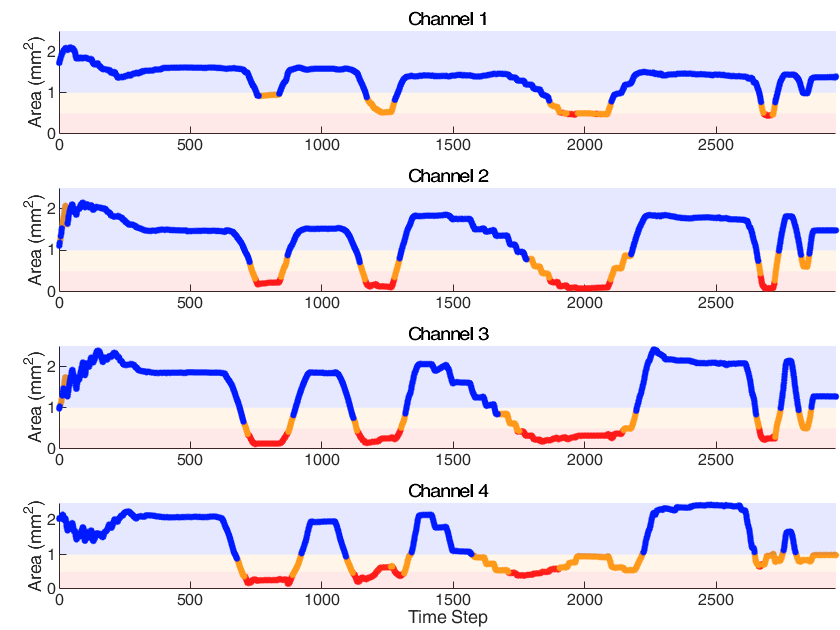

figure
% title('Predicted vs Measured Areas')
for i_ch=1:length(YValidation)
    ax_area(i_ch) = subplot_er(4,1,i_ch);
    hold on
    title(sprintf('Channel %i', i_ch), 'FontSize',11)
    for i_class = 1:numClasses        
        % shade the region corresponding to this prediction
        fill([0 0 length(YPred{i_ch}) length(YPred{i_ch})],...
             [bin_edges(i_class) bin_edges(i_class+1) bin_edges(i_class+1) bin_edges(i_class)],...
             class_colors(i_class,:), 'FaceAlpha',0.1, 'EdgeColor','none')
        
        % find all samples with this prediction
        idx = find(YPred{i_ch} == bin_names(i_class));
        
        % plot all samples with this prediction
        plot(idx,trial6.A{i_ch}(1,idx),'.', 'Color',class_colors(i_class,:), 'MarkerSize',10)
    end
    
    xlim([0 length(YPred{i_ch})])
    ylim([0 2.5])
    ylabel('Area (mm^2)', 'FontSize',10)
end
linkaxes(ax_area,'x')
xlabel("Time Step")
hold off